# Basic Exploration of Analysis of Datalogger

Read the data into a MATLAB "table" object

A MATLAB "table" is equivalent to a Pandas DataFrame in Python.

T = readtable("2023-11-08 Sitting still in class.txt");

Plot the magnitude of the acceleration components over time.

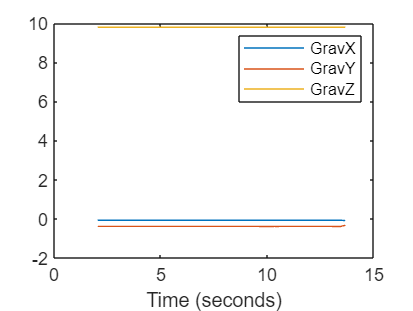

T.secs = T.t / 1000;
plot(T.secs, T.GravX);
hold on
plot(T.secs, T.GravY);
plot(T.secs, T.GravZ);
hold off
legend("GravX", "GravY", "GravZ")
xlabel("Time (seconds)");

Rotation Matrix

See example by MATLAB (https://www.mathworks.com/help/robotics/coordinate-system-transformations.html)

%https://www.mathworks.com/help/vision/ref/rotvec2mat3d.html

t = T(300,:); % Just the first row

rotVec = deg2rad([t.OrX, t.OrY, t.OrZ]);
quat = [t.QuatW, t.QuatX, t.QuatX, t.QuatZ];
rotMat = rotvec2mat3d(rotVec); % note: rotvec2mat3d requires MATLAB's Computer Vision Toolbox

[t.OrX, t.OrY, t.OrZ]

ans =    35.6300   -1.0600 -113.7500


rotVec

rotVec =     0.6219   -0.0185   -1.9853


gravVec = [t.GravX, t.GravY, t.GravZ]

gravVec =    -0.1800    8.9700   -3.9500


gravVec * rotx(t.OrX) * roty(t.OrY) * rotz(t.OrZ) % note: rotx, roty, rotz require MATLAB's Phased Array System Toolbox

ans =    -4.4318   -2.3172   -8.4312


gravVec * rotx(t.OrX) * roty(t.OrY) * rotz(t.OrZ) % note: rotx, roty, rotz require MATLAB's Phased Array System Toolbox

ans =    -4.4318   -2.3172   -8.4312


gravVec * eul2rotm(rotVec, "ZYX")

ans =     5.0052    0.7223    8.3977


gravVec * quat2rotm(quat)

ans =     9.0189   -0.2051   -3.8357


gravVec * inv(quat2rotm(quat))

ans =     6.8297    3.9900    5.7906


quat2eul([t.QuatX, t.QuatY, t.QuatZ, t.QuatW])

ans =     1.1556   -0.0191   -0.5930


quat2eul([t.QuatX, t.QuatY, t.QuatZ, t.QuatW],"XYZ")

ans =    -0.2491   -0.5443    1.0799


quat2eul([t.QuatW, t.QuatX, t.QuatX, t.QuatZ], "XYZ")

ans =     2.3022    0.3649   -1.4065


gravVec * inv(eul2rotm(rotVec, "ZXZ"))

ans =     8.7830    1.9638   -3.8855


gravVec * rotx(-t.OrZ) * rotz(-t.OrY) * rotx(-t.OrX) % note: rotx, roty, rotz require MATLAB's Phased Array System Toolbox

ans =    -0.3137   -2.0151   -9.5884





disp("Ok, let's at least get orientation from Euler")

Ok, let's at least get orientation from Euler


t = T(300,:); % Just the first row
[t.OrX, t.OrY, t.OrZ]

ans =    35.6300   -1.0600 -113.7500


rad2deg(quat2eul([t.QuatW, t.QuatX, t.QuatY, t.QuatZ]))

ans =   -33.9781    1.0965  113.7917



myrotm = quat2rotm([t.QuatW, t.QuatX, t.QuatY, t.QuatZ]);
gravVec

gravVec =    -0.1800    8.9700   -3.9500


[0, 0, 9.8] * myrotm

ans =    -0.1875    8.9655   -3.9527


gravVec * inv(myrotm)

ans =     0.0039   -0.0078    9.8028



myrotm2 = (rotz(t.OrX) * roty(-t.OrY) * rotx(-t.OrZ));
[0, 0, 9.8] * myrotm2

ans =    -0.1813    8.9685   -3.9462


gravVec * inv(myrotm2)

ans =    -0.0006    0.0031    9.8028


% Calibration: Sys=3 Gyro=3 Accel=3 Mag=3
% --
% Orient:	x= 59.44 |	y= -69.69 |	z= -17.75
% Gyro:	x= 0.03 |	y= -0.01 |	z= -0.01
% Linear:	x= -0.01 |	y= 0.01 |	z= -0.02
% Mag:	x= 12.75 |	y= 13.19 |	z= -38.38
% Accl:	x= -9.20 |	y= 1.05 |	z= 3.21
% Gravity:	x= -9.19 |	y= 1.03 |	z= 3.24


% Calibration: Sys=2 Gyro=3 Accel=3 Mag=3
% --
% Orient:	x= 106.12 |	y= -0.81 |	z= 77.56
% Gyro:	x= 0.03 |	y= 0.02 |	z= -0.03
% Linear:	x= -0.08 |	y= -0.30 |	z= 0.22
% Mag:	x= -48.25 |	y= 10.38 |	z= -25.25
% Accl:	x= -0.22 |	y= -9.87 |	z= 2.33
% Gravity:	x= -0.14 |	y= -9.57 |	z= 2.10


%orVec = [59.44, -69.69, -17.75];
orVec = [106.12 , -0.81, 77.56];
gravVec = [-0.14, -9.57, 2.10];
[0, 0, -9.8] * rotz(orVec(1)) * roty(orVec(2)) * rotx(orVec(3)) % note: rotx, roty, rotz require MATLAB's Phased Array System Toolbox

ans =    -0.1385   -9.5690   -2.1109


myrotm = (rotz(orVec(1)) * roty(orVec(2)) * rotx(orVec(3)));
rotated = [0, 0, -9.8] * myrotm

rotated =    -0.1385   -9.5690   -2.1109


rotated * (myrotm)^-1

ans =     0.0000    0.0000   -9.8000


%gravVec * rotx(-orVec(3)) * roty(-orVec(2)) * rotz(-orVec(3)) % note: rotx, roty, rotz require MATLAB's Phased Array System Toolbox


T.gravVec = [T.GravX, T.GravY, T.GravZ];
T.orVec = [T.OrX, T.OrY, T.OrZ];
T.gravVec * deg2rad(T.orVec)

quat2rotm(quat)

